# Example: Linear System

The code below gives a reachability analysis example for linear systems in CORA.

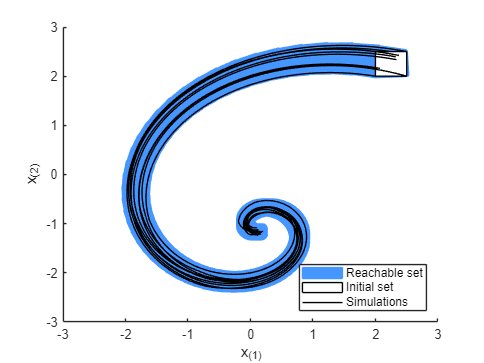

% System Dynamics ---------------------------------------------------------

A = [-0.7 -2;2 -0.7]; B = [1;1]; c = [-2;-1];
sys = linearSys(A,B,c);

% Parameters --------------------------------------------------------------

params.tFinal = 5;
params.R0 = zonotope(interval([2;2],[2.5;2.5]));
params.U = zonotope(interval(-0.1,0.1));

options.timeStep = 0.05;
options.zonotopeOrder = 10;
options.taylorTerms = 5;

% Reachability Analysis ---------------------------------------------------

R = reach(sys,params,options);

% Simulation --------------------------------------------------------------

simOpt.points = 10;
simRes = simulateRandom(sys,params,simOpt);

% Visualization -----------------------------------------------------------

figure; hold on;

useCORAcolors("CORA:contDynamics")
plot(R,[1,2],'DisplayName','Reachable set')
plot(R.R0,[1,2],'DisplayName','Initial set')
plot(simRes,[1,2],'DisplayName','Simulations')

legend('Location','southeast')
xlabel('x_{(1)}')
ylabel('x_{(2)}')